f = @(x) x^2-x-2;
g1 = @(x) x^2-2;
g2 = @(x) 1+ 2/x;
g3 = @(x) -(2+x)^0.5;
[res1, iter_err1] = fixed_point_iter(g1, -0.5, 10^-4, 1000);
[res2, iter_err2] = fixed_point_iter(g2, -0.5, 10^-4, 1000);
[res3, iter_err3] = fixed_point_iter(g3, -0.5, 10^-4, 1000);
%g2 non interseca nemmeno f quindi certamente non puo' convergere ad una
%delle radici, viceversa g1 e g3 intersecano f ed infatti scegliendo x0,
%"abbstanza vicino" al punto in cui si intersecano il metodo trova le
%radici di f
hold on
fplot(f, '-r');

fplot(g1, '-g');

fplot(g2, '-y');

fplot(g3, '-b');

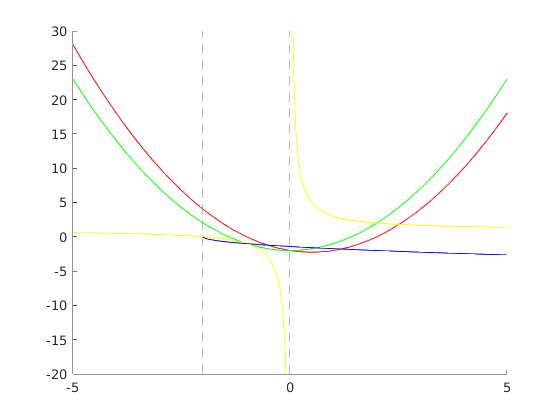

hold off